# Resurging Disease Model

*Author:* Zachary del Rosario, Fall 2020

*Purpose:* Generate data with a known ground-truth for students to fit a model against, this time with a resurgance term.

## Generate Data

Generate data under a ground-truth setting.

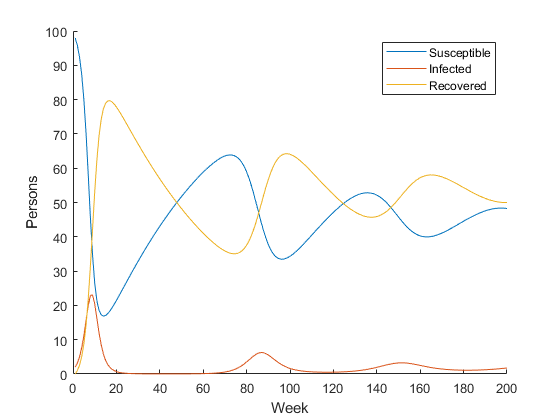

% Define simulation initial state
s_0 = 98;
i_0 = 2;
r_0 = 0;
% Define parameters
beta = 1 / 90;    % Infection rate (New / Susceptible / Infected / week)
gamma = 1 / 2;    % Recovery rate (1 / week)
epsilon = 1 / 60; % Immunity decay rate (1 / week)

% Run simulation
[S, I, R, W] = fcn_simulate(s_0, i_0, r_0, beta, gamma, epsilon, 200);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

We'll use this model as the ground-truth for a student exercise.

It's easier to save/load/filter data with a table. Package the results in a table:

tab_results = table(W', S', I', R', 'VariableNames', {'W', 'S', 'I', 'R'})

tab_results = 200×4 table
    W       S         I         R   
    __    ______    ______    ______

     1        98         2         0
     2    95.822    3.1778         1
     3    92.456    4.9722    2.5722
     4    87.391     7.594    5.0155
     5      80.1    11.171    8.7289
     6    70.304    15.528    14.169
     7     58.41    19.893    21.696
     8    45.861    22.857    31.281
     9    34.735    23.076    42.189
    10    26.532    20.444    53.024
    11    21.389    16.249    62.362
    12    18.567    11.986    69.447
    13    17.251    8.4658    74.283
    14    16.867    5.8557    77.278
    15    17.057    4.0252    78.917
    16     17.61    2.7755    79.615


## Mask the Data

Mask the data on a detection threshold

% Set a lower detection threshold
min_i = 1;
wk1_min = 0; wk1_max = 20;
wk2_min = 60; wk2_max = 120;
% Filter the data based on thresholds
tab_tmp1 = tab_results( ...
    (tab_results.I >= min_i) & ...
    (tab_results.W >= wk1_min) & ...
    (tab_results.W <= wk1_max), ...
    :);
tab_wave1 = apply(@round, tab_tmp1)

tab_wave1 = 18×4 table
    W     S     I     R 
    __    __    __    __

     1    98     2     0
     2    96     3     1
     3    92     5     3
     4    87     8     5
     5    80    11     9
     6    70    16    14
     7    58    20    22
     8    46    23    31
     9    35    23    42
    10    27    20    53
    11    21    16    62
    12    19    12    69
    13    17     8    74
    14    17     6    77
    15    17     4    79
    16    18     3    80



tab_tmp2 = tab_results( ...
    (tab_results.I >= min_i) & ...
    (tab_results.W >= wk2_min) & ...
    (tab_results.W<= wk2_max), ...
    :);
tab_wave2 = apply(@round, tab_tmp2)

tab_wave2 = 32×4 table
    W     S     I    R 
    __    __    _    __

    73    64    1    35
    74    64    1    35
    75    63    1    35
    76    63    2    35
    77    62    2    36
    78    61    3    36
    79    60    3    37
    80    59    4    38
    81    57    4    39
    82    55    5    40
    83    53    5    42
    84    51    6    44
    85    48    6    46
    86    46    6    48
    87    44    6    50
    88    41    6    52


Write the data to a csv.

writetable(tab_wave1(tab_wave1.W <= 6, ["W", "I"]), "infected.csv")
writetable(tab_wave1(:, ["W", "I"]), "wave1.csv")
writetable(tab_wave2(:, ["W", "I"]), "wave2.csv")